Monte Carlo

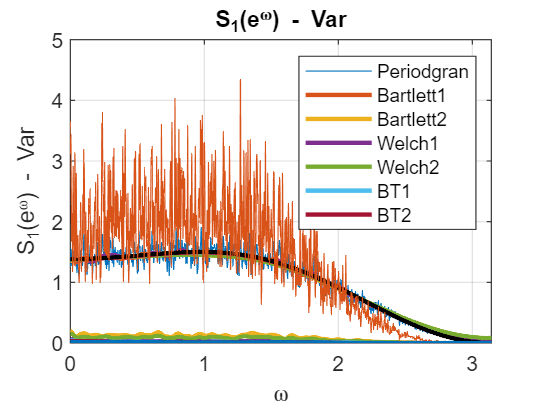

Mc=100;
N=1024;
M=4096;
%% Analytical Calculation
omega = linspace(0,pi,2049);
S_x1_Analytic = 1 + 9/13*(cos(omega)) -4/13*(cos(2*omega));
S_x2_Analytic = 0.51./(1.49-1.4*cos(omega));
 
%% Generating the signal 'Mc' times - "Monte Carlo"
S_1_Periodgram = zeros(Mc,M/2+1);
S_1_Bartlett1 = zeros(Mc,M/2+1);
S_1_Bartlett2 = zeros(Mc,M/2+1);
S_1_Welch1 = zeros(Mc,M/2+1);
S_1_Welch2 = zeros(Mc,M/2+1);
S_1_Blackman_Tukey1 = zeros(Mc,M/2+1);
S_1_Blackman_Tukey2 = zeros(Mc,M/2+1);
 
S_2_Periodgram = zeros(Mc,M/2+1);
S_2_Bartlett1 = zeros(Mc,M/2+1);
S_2_Bartlett2 = zeros(Mc,M/2+1);
S_2_Welch1 = zeros(Mc,M/2+1);
S_2_Welch2 = zeros(Mc,M/2+1);
S_2_Blackman_Tukey1 = zeros(Mc,M/2+1);
S_2_Blackman_Tukey2 = zeros(Mc,M/2+1);
 
sigma_1 = 1/sqrt(26);
sigma_2 = sqrt(0.51);
 
for i = 1:Mc
    w_1 = sigma_1*randn(1,N);
    w_2 = sigma_2*randn(1,2*N);
    
    x_1 = filter([1,-3,-4],1,w_1);
    x_2_full = filter(1,[1,-0.7],w_2);
    x_2 = x_2_full(N+1:2*N);
    
    S_1_Periodgram(i,:) = Periodgram(x_1, N, M);
    S_1_Bartlett1(i,:) = Bartlett(x_1, 16, 64, M);
    S_1_Bartlett2(i,:) = Bartlett(x_1, 64, 16, M);
    S_1_Welch1(i,:) = Welch(x_1, 61, 64, 48, M);
    S_1_Welch2(i,:) = Welch(x_1, 253, 16, 12, M);
    S_1_Blackman_Tukey1(i,:) = Blackman_Tukey(x_1, N, 4, M);
    S_1_Blackman_Tukey2(i,:) = Blackman_Tukey(x_1, N, 2, M);
    
    S_2_Periodgram(i,:) = Periodgram(x_2, N, M);
    S_2_Bartlett1(i,:) = Bartlett(x_2, 16, 64, M);
    S_2_Bartlett2(i,:) = Bartlett(x_2, 64, 16, M);
    S_2_Welch1(i,:) = Welch(x_2, 61, 64, 48, M);
    S_2_Welch2(i,:) = Welch(x_2, 253, 16, 12, M);
    S_2_Blackman_Tukey1(i,:) = Blackman_Tukey(x_2, N, 4, M);
    S_2_Blackman_Tukey2(i,:) = Blackman_Tukey(x_2, N, 2, M);
end

%% Summarizing And Printing for x1
sum_Periodgram_x_1 = Summary(S_1_Periodgram, S_x1_Analytic, Mc);
sum_Bartlett1_x_1 = Summary(S_1_Bartlett1, S_x1_Analytic, Mc);
sum_Bartlett2_x_1 = Summary(S_1_Bartlett2, S_x1_Analytic, Mc);
sum_Welch1_x_1 = Summary(S_1_Welch1, S_x1_Analytic, Mc);
sum_Welch2_x_1 = Summary(S_1_Welch2, S_x1_Analytic, Mc);
sum_Blackman_Tukey1_x_1 = Summary(S_1_Blackman_Tukey1, S_x1_Analytic, Mc);
sum_Blackman_Tukey2_x_1 = Summary(S_1_Blackman_Tukey2, S_x1_Analytic, Mc);
    
figure(1); % Avg Sx1
plot(omega, sum_Periodgram_x_1(1,:));
hold on
plot(omega, sum_Bartlett1_x_1(1,:), 'linewidth', 2);
plot(omega, sum_Bartlett2_x_1(1,:), 'linewidth', 2);
plot(omega, sum_Welch1_x_1(1,:), 'linewidth', 2);
plot(omega, sum_Welch2_x_1(1,:), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey1_x_1(1,:)), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey2_x_1(1,:)), 'linewidth', 2);
plot(omega, S_x1_Analytic, 'k', 'linewidth', 2);
legend('Periodgran', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2','Analitic');
title('S_x_1(e^j^\omega) - Avg');
ylabel('S_x_1(e^j^\omega) - Avg');
xlabel('\omega');
grid on

figure(2); % Variance Sx1
semilogy(omega, sum_Periodgram_x_1(2,:));
hold on
semilogy(omega, sum_Bartlett1_x_1(2,:), 'linewidth', 2);
semilogy(omega, sum_Bartlett2_x_1(2,:), 'linewidth', 2);
semilogy(omega, sum_Welch1_x_1(2,:), 'linewidth', 2);
semilogy(omega, sum_Welch2_x_1(2,:), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey1_x_1(2,:)), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey2_x_1(2,:)), 'linewidth', 2);
title('S_x_1(e^j^\omega) - Var');
ylabel('S_x_1(e^j^\omega) - Var');
xlabel('\omega');
legend('Periodgran', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
grid on

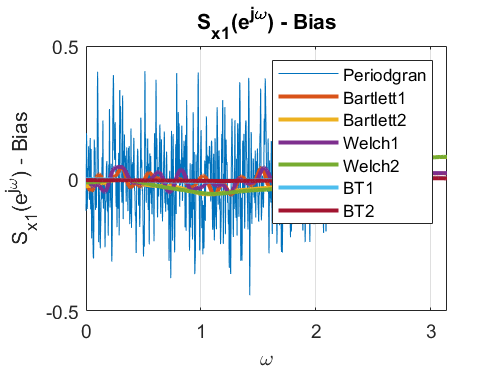


figure(3); % Bias Sx1
plot(omega, sum_Periodgram_x_1(3,:));
hold on
plot(omega, sum_Bartlett1_x_1(3,:), 'linewidth', 2);
plot(omega, sum_Bartlett2_x_1(3,:), 'linewidth', 2);
plot(omega, sum_Welch1_x_1(3,:), 'linewidth', 2);
plot(omega, sum_Welch2_x_1(3,:), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey1_x_1(3,:)), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey2_x_1(3,:)), 'linewidth', 2);
legend('Periodgran', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
title('S_x_1(e^j^\omega) - Bias');
ylabel('S_x_1(e^j^\omega) - Bias');
xlabel('\omega');
grid on

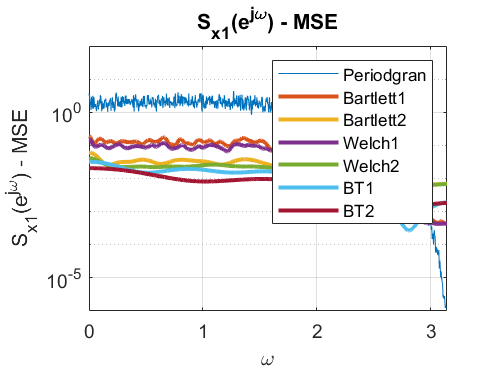


figure(4); % MSE Sx1
semilogy(omega, sum_Periodgram_x_1(4,:));
hold on
semilogy(omega, sum_Bartlett1_x_1(4,:), 'linewidth', 2);
semilogy(omega, sum_Bartlett2_x_1(4,:), 'linewidth', 2);
semilogy(omega, sum_Welch1_x_1(4,:), 'linewidth', 2);
semilogy(omega, sum_Welch2_x_1(4,:), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey1_x_1(4,:)), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey2_x_1(4,:)), 'linewidth', 2);
legend('Periodgran', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
title('S_x_1(e^j^\omega) - MSE');
ylabel('S_x_1(e^j^\omega) - MSE');
xlabel('\omega');
grid on

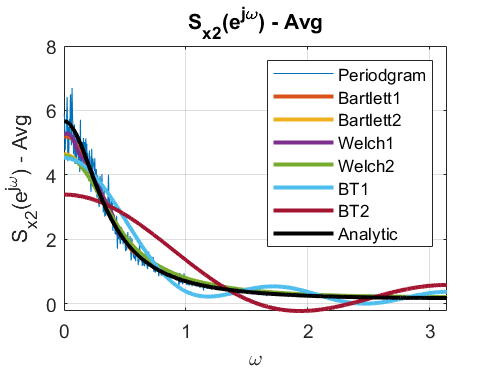


% Summarizing And Printing for x2
sum_Periodgram_x_2 = Summary(S_2_Periodgram, S_x2_Analytic, Mc);
sum_Bartlett1_x_2 = Summary(S_2_Bartlett1, S_x2_Analytic, Mc);
sum_Bartlett2_x_2 = Summary(S_2_Bartlett2, S_x2_Analytic, Mc);
sum_Welch1_x_2 = Summary(S_2_Welch1, S_x2_Analytic, Mc);
sum_Welch2_x_2 = Summary(S_2_Welch2, S_x2_Analytic, Mc);
sum_Blackman_Tukey1_x_2 = Summary(S_2_Blackman_Tukey1, S_x2_Analytic, Mc);
sum_Blackman_Tukey2_x_2 = Summary(S_2_Blackman_Tukey2, S_x2_Analytic, Mc);
 
    
figure(5); % Avg Sx2
plot(omega, sum_Periodgram_x_2(1,:));
hold on
plot(omega, sum_Bartlett1_x_2(1,:), 'linewidth', 2);
plot(omega, sum_Bartlett2_x_2(1,:), 'linewidth', 2);
plot(omega, sum_Welch1_x_2(1,:), 'linewidth', 2);
plot(omega, sum_Welch2_x_2(1,:), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey1_x_2(1,:)), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey2_x_2(1,:)), 'linewidth', 2);
plot(omega, S_x2_Analytic, 'k', 'linewidth', 2);
legend('Periodgram', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2', 'Analytic');
title('S_x_2(e^j^\omega) - Avg');
ylabel('S_x_2(e^j^\omega) - Avg');
xlabel('\omega');
grid on

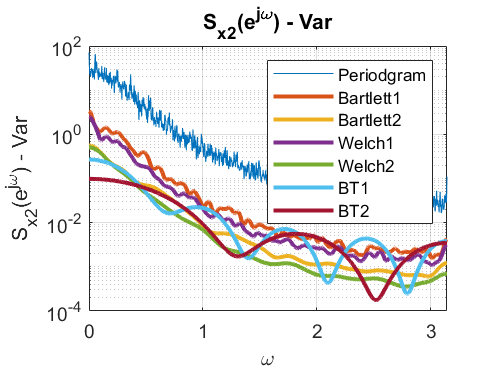


figure(6); % Variance Sx2
semilogy(omega, sum_Periodgram_x_2(2,:));
hold on
semilogy(omega, sum_Bartlett1_x_2(2,:), 'linewidth', 2);
semilogy(omega, sum_Bartlett2_x_2(2,:), 'linewidth', 2);
semilogy(omega, sum_Welch1_x_2(2,:), 'linewidth', 2);
semilogy(omega, sum_Welch2_x_2(2,:), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey1_x_2(2,:)), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey2_x_2(2,:)), 'linewidth', 2);
legend('Periodgram', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
title('S_x_2(e^j^\omega) - Var');
ylabel('S_x_2(e^j^\omega) - Var');
xlabel('\omega');
grid on

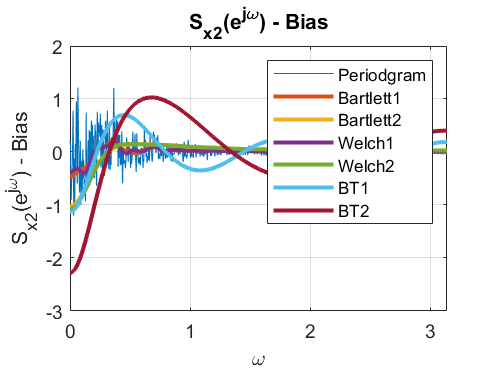


figure(7); % Bias Sx2
plot(omega, sum_Periodgram_x_2(3,:));
hold on
plot(omega, sum_Bartlett1_x_2(3,:), 'linewidth', 2);
plot(omega, sum_Bartlett2_x_2(3,:), 'linewidth', 2);
plot(omega, sum_Welch1_x_2(3,:), 'linewidth', 2);
plot(omega, sum_Welch2_x_2(3,:), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey1_x_2(3,:)), 'linewidth', 2);
plot(omega, real(sum_Blackman_Tukey2_x_2(3,:)), 'linewidth', 2);
legend('Periodgram', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
title('S_x_2(e^j^\omega) - Bias');
ylabel('S_x_2(e^j^\omega) - Bias');
xlabel('\omega');
grid on

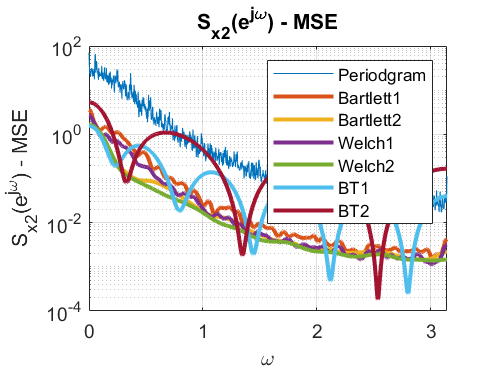


figure(8); % MSE Sx2
semilogy(omega, sum_Periodgram_x_2(4,:));
hold on
semilogy(omega, sum_Bartlett1_x_2(4,:), 'linewidth', 2);
semilogy(omega, sum_Bartlett2_x_2(4,:), 'linewidth', 2);
semilogy(omega, sum_Welch1_x_2(4,:), 'linewidth', 2);
semilogy(omega, sum_Welch2_x_2(4,:), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey1_x_2(4,:)), 'linewidth', 2);
semilogy(omega, real(sum_Blackman_Tukey2_x_2(4,:)), 'linewidth', 2);
legend('Periodgram', 'Bartlett1', 'Bartlett2', 'Welch1', 'Welch2', 'BT1', 'BT2');
title('S_x_2(e^j^\omega) - MSE');
ylabel('S_x_2(e^j^\omega) - MSE');
xlabel('\omega');
grid on


%% Part D
mean_Var_x1 = zeros(1,7);
mean_Var_x1(1) = mean(sum_Periodgram_x_1(2,:));
mean_Var_x1(2) = mean(sum_Bartlett1_x_1(2,:));
mean_Var_x1(3) = mean(sum_Bartlett2_x_1(2,:));
mean_Var_x1(4) = mean(sum_Welch1_x_1(2,:));
mean_Var_x1(5) = mean(sum_Welch2_x_1(2,:));
mean_Var_x1(6) = mean(sum_Blackman_Tukey1_x_1(2,:));
mean_Var_x1(7) = mean(sum_Blackman_Tukey2_x_1(2,:));
mean_Bias_x1 = zeros(1,7);
mean_Bias_x1(1) = mean(sum_Periodgram_x_1(3,:).^2);
mean_Bias_x1(2) = mean(sum_Bartlett1_x_1(3,:).^2);
mean_Bias_x1(3) = mean(sum_Bartlett2_x_1(3,:).^2);
mean_Bias_x1(4) = mean(sum_Welch1_x_1(3,:).^2);
mean_Bias_x1(5) = mean(sum_Welch2_x_1(3,:).^2);
mean_Bias_x1(6) = mean(sum_Blackman_Tukey1_x_1(3,:).^2);
mean_Bias_x1(7) = mean(sum_Blackman_Tukey2_x_1(3,:).^2);
mean_MSE_x1 = zeros(1,7);
mean_MSE_x1(1) = mean(sum_Periodgram_x_1(4,:));
mean_MSE_x1(2) = mean(sum_Bartlett1_x_1(4,:));
mean_MSE_x1(3) = mean(sum_Bartlett2_x_1(4,:));
mean_MSE_x1(4) = mean(sum_Welch1_x_1(4,:));
mean_MSE_x1(5) = mean(sum_Welch2_x_1(4,:));
mean_MSE_x1(6) = mean(sum_Blackman_Tukey1_x_1(4,:));
mean_MSE_x1(7) = mean(sum_Blackman_Tukey2_x_1(4,:));
mean_Var_x2 = zeros(1,7);
mean_Var_x2(1) = mean(sum_Periodgram_x_2(2,:));
mean_Var_x2(2) = mean(sum_Bartlett1_x_2(2,:));
mean_Var_x2(3) = mean(sum_Bartlett2_x_2(2,:));
mean_Var_x2(4) = mean(sum_Welch1_x_2(2,:));
mean_Var_x2(5) = mean(sum_Welch2_x_2(2,:));
mean_Var_x2(6) = mean(sum_Blackman_Tukey1_x_2(2,:));
mean_Var_x2(7) = mean(sum_Blackman_Tukey2_x_2(2,:));
mean_Bias_x2 = zeros(1,7);
mean_Bias_x2(1) = mean(sum_Periodgram_x_2(3,:).^2);
mean_Bias_x2(2) = mean(sum_Bartlett1_x_2(3,:).^2);
mean_Bias_x2(3) = mean(sum_Bartlett2_x_2(3,:).^2);
mean_Bias_x2(4) = mean(sum_Welch1_x_2(3,:).^2);
mean_Bias_x2(5) = mean(sum_Welch2_x_2(3,:).^2);
mean_Bias_x2(6) = mean(sum_Blackman_Tukey1_x_2(3,:).^2);
mean_Bias_x2(7) = mean(sum_Blackman_Tukey2_x_2(3,:).^2);
mean_MSE_x2 = zeros(1,7);
mean_MSE_x2(1) = mean(sum_Periodgram_x_2(4,:));
mean_MSE_x2(2) = mean(sum_Bartlett1_x_2(4,:));
mean_MSE_x2(3) = mean(sum_Bartlett2_x_2(4,:));
mean_MSE_x2(4) = mean(sum_Welch1_x_2(4,:));
mean_MSE_x2(5) = mean(sum_Welch2_x_2(4,:));
mean_MSE_x2(6) = mean(sum_Blackman_Tukey1_x_2(4,:));
mean_MSE_x2(7) = mean(sum_Blackman_Tukey2_x_2(4,:));
mean_x_1 = real([mean_Var_x1;mean_Bias_x1;mean_MSE_x1]);
mean_x_2 = real([mean_Var_x2;mean_Bias_x2;mean_MSE_x2]);
